# Week 1: From a Physics Model to a Computational Experiment

- Programming Fundamentals through a Physical Model

This Live Script follows one complete computational-physics cycle: physical question -> MATLAB fundamentals -> numerical model -> validation. Run it from a fresh MATLAB session and change one parameter at a time.

## 1. Setup and parameter record

A colleague should be able to see the physical parameters and their units.

clearvars; close all; clc
format shortG

N0 = 1000;             % initial population, nuclei
T_half_h = 6.0;        % half-life, h
tMax_h = 24.0;         % final time, h
dt_h = 0.5;            % Euler step, h
lambda_per_h = log(2)/T_half_h;  % decay constant, 1/h

fprintf('lambda = %.6f 1/h\n', lambda_per_h)

lambda = 0.115525 1/h


fprintf('lambda*dt = %.6f (dimensionless)\n', lambda_per_h*dt_h)

lambda*dt = 0.057762 (dimensionless)


## 2. Prediction before computing

Before running the numerical method, predict the following: * What fraction remains after one half-life? * What fraction remains after four half-lives? * Can a physically meaningful population be negative?

exactFractionAtHalfLife = exp(-lambda_per_h*T_half_h);
exactFractionAtFourHalfLives = exp(-lambda_per_h*4*T_half_h);
fprintf('Exact fraction after one half-life = %.6f\n', exactFractionAtHalfLife)

Exact fraction after one half-life = 0.500000


fprintf('Exact fraction after four half-lives = %.6f\n', exactFractionAtFourHalfLives)

Exact fraction after four half-lives = 0.062500


## 3. Exact solution: a reference answer

The exact solution is a benchmark for the numerical experiment.

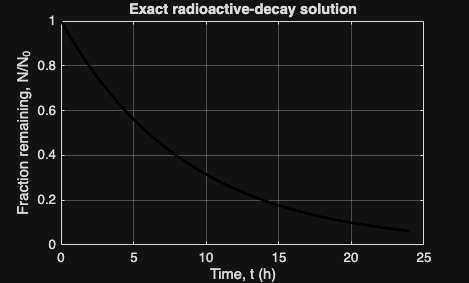

t_h = 0:dt_h:tMax_h;
N_exact = N0*exp(-lambda_per_h*t_h);

figure('Name','Exact radioactive decay')
plot(t_h,N_exact/N0,'k-','LineWidth',2)
grid on
xlabel('Time, t (h)')
ylabel('Fraction remaining, N/N_0')
title('Exact radioactive-decay solution')

## 4. Forward Euler time stepping

The discrete update is N(n+1) = N(n)*(1 - lambda*dt). MATLAB arrays start at index 1, so N(1) represents N_0.

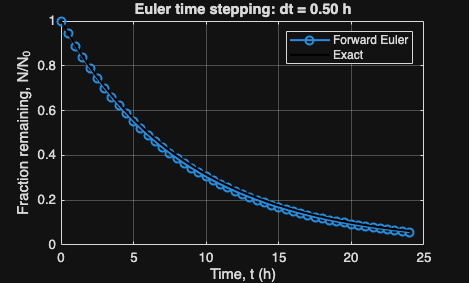

N = zeros(size(t_h));
N(1) = N0;

for n = 1:numel(t_h)-1
    N(n+1) = N(n)*(1 - lambda_per_h*dt_h);
end

N_euler_fraction = N/N0;
N_exact_fraction = N_exact/N0;
finalRelativeError = abs(N(end)-N_exact(end))/N_exact(end);

figure('Name','Euler versus exact')
plot(t_h,N_euler_fraction,'o-', ...
     t_h,N_exact_fraction,'k-','LineWidth',1.5)
grid on
xlabel('Time, t (h)')
ylabel('Fraction remaining, N/N_0')
legend('Forward Euler','Exact','Location','northeast')
title(sprintf('Euler time stepping: dt = %.2f h',dt_h))


fprintf('Euler fraction at tMax = %.6f\n',N_euler_fraction(end))

Euler fraction at tMax = 0.057505


fprintf('Exact fraction at tMax = %.6f\n',N_exact_fraction(end))

Exact fraction at tMax = 0.062500


fprintf('Final relative error = %.3f %%\n',100*finalRelativeError)

Final relative error = 7.992 %


## 5. Timestep experiment and convergence

Smaller dt should approach the exact curve, but it requires more steps.

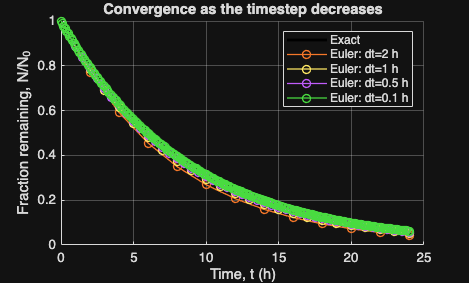

dtValues_h = [2.0 1.0 0.5 0.1];
lambdaDt = lambda_per_h*dtValues_h;
finalEulerFraction = zeros(size(dtValues_h));
relativeErrorPercent = zeros(size(dtValues_h));
stepCount = zeros(size(dtValues_h));

figure('Name','Timestep comparison')
hold on
plot(t_h,N_exact_fraction,'k-','LineWidth',2)

for k = 1:numel(dtValues_h)
    dtCurrent_h = dtValues_h(k);
    tCurrent_h = 0:dtCurrent_h:tMax_h;
    NCurrent = zeros(size(tCurrent_h));
    NCurrent(1) = N0;

    for n = 1:numel(tCurrent_h)-1
        NCurrent(n+1) = NCurrent(n)*(1 - lambda_per_h*dtCurrent_h);
    end

    exactAtFinal = N0*exp(-lambda_per_h*tMax_h);
    finalEulerFraction(k) = NCurrent(end)/N0;
    relativeErrorPercent(k) = 100*abs(NCurrent(end)-exactAtFinal)/exactAtFinal;
    stepCount(k) = numel(tCurrent_h)-1;
    plot(tCurrent_h,NCurrent/N0,'o-','LineWidth',1.0)
end

grid on
xlabel('Time, t (h)')
ylabel('Fraction remaining, N/N_0')
legend('Exact','Euler: dt=2 h','Euler: dt=1 h', ...
       'Euler: dt=0.5 h','Euler: dt=0.1 h', ...
       'Location','northeast')
title('Convergence as the timestep decreases')
hold off


resultsTable = table(dtValues_h(:),lambdaDt(:),stepCount(:), ...
    finalEulerFraction(:),relativeErrorPercent(:), ...
    'VariableNames',{'dt_h','lambda_dt','steps','EulerFractionAt24h','RelativeErrorPercent'});
disp(resultsTable)

    dt_h    lambda_dt    steps    EulerFractionAt24h    RelativeErrorPercent
    ____    _________    _____    __________________    ____________________

      2      0.23105       12          0.042735                31.624       
      1      0.11552       24          0.052536                15.942       
    0.5     0.057762       48          0.057505                7.9924       
    0.1     0.011552      240          0.061499                 1.601       



## 6. Validation checks

These checks are simple evidence, not a substitute for physical reasoning.

assert(abs(N(1)-N0) < eps(N0), 'Initial condition is not stored in N(1).')
assert(abs(exactFractionAtHalfLife-0.5) < 1e-12, ...
    'Half-life reference check failed.')
assert(abs(N_exact_fraction(end)-0.0625) < 1e-12, ...
    'Four-half-life reference check failed.')
assert(all(isfinite(N)), 'The numerical solution contains a non-finite value.')
assert(all(N >= 0), 'The chosen timestep produced a negative population.')
assert(relativeErrorPercent(end) < 2.0, ...
    'The finest timestep did not reach the expected accuracy.')

fprintf('Validation checks passed for the chosen parameters.\n')

Validation checks passed for the chosen parameters.


## 7. Stability and physical admissibility warning

For this decay update, lambda*dt must be dimensionless. If lambda*dt > 1, the factor (1 - lambda*dt) becomes negative and the computed population can become unphysical even though the formula is syntactically correct.

unsafeDt_h = 10.0;
unsafeFactor = 1 - lambda_per_h*unsafeDt_h;
fprintf('For dt = %.1f h, 1 - lambda*dt = %.3f.\n',unsafeDt_h,unsafeFactor)

For dt = 10.0 h, 1 - lambda*dt = -0.155.


fprintf('This is a warning to reduce dt before trusting the result.\n')

This is a warning to reduce dt before trusting the result.


## 8. Student challenge

Change one value at a time and rerun the relevant sections: 1. Set T_half_h = 3.0 and predict the new fraction at 24 h. 2. Set dt_h = 0.1 and compare the error with dt_h = 0.5. 3. Set N0 = 5000 and verify that N/N0 is unchanged. 4. Add a caption explaining which validation check you performed.

challengeT_half_h = 3.0;
challengeDt_h = 0.25;
challengeLambda_per_h = log(2)/challengeT_half_h;
challengeTime_h = 0:challengeDt_h:tMax_h;
challengeN = zeros(size(challengeTime_h));
challengeN(1) = N0;

for n = 1:numel(challengeTime_h)-1
    challengeN(n+1) = challengeN(n)*(1 - challengeLambda_per_h*challengeDt_h);
end

fprintf('Challenge fraction at 24 h = %.6f\n',challengeN(end)/N0)

Challenge fraction at 24 h = 0.003307


fprintf('Challenge exact fraction at 24 h = %.6f\n', ...
    exp(-challengeLambda_per_h*tMax_h))

Challenge exact fraction at 24 h = 0.003906


## Exit ticket

Write three sentences before leaving the practical: 1. State the model equation and one assumption. 2. State the MATLAB line that advances one time step. 3. State the evidence that makes your chosen dt acceptable.